# Comparing Birdscan insect/bird

**Raphaël Nussbaumer**

## **Load WR data**

load('../data/dc_corr')
ii_d = [6 28 8];% deflg, demem, frmtc

## Load Insec/Bird Birdscan

load('BS/Sempach_2018_combined')

add value of BSs location.

lat = 47.128054;
lon = 8.192377;
alt = 540;

Add seasonal variables

t=datetime('2018-01-01'):datetime('2019-01-01');
season = datetime([737121 737184 737273 737384 737121+365],'ConvertFrom','datenum');
season_label = {'Spring (02-Mar  - 04-May)','Summer (4-May - 1-Aug)','Autumn (1-Aug - 20-Nov)','Winter (20-Nov - 02-Mar)'};

## Filter BSs data

Define the thresholds of the filters

minprobinsect=.7;
minprobbird=.3;
maxalt = 1000-alt;
minalt = 600-alt;

Apply filter

BSs = BS(BS.altitude>minalt & BS.altitude<maxalt & (BS.predicted_class_prob>minprobinsect|BS.isBird) & (BS.predicted_class_prob>minprobbird|~BS.isBird) & ~isnan(BS.flight),:);

Load Birdscan data corrected for volume sample. 

% Tb = readtable('MTRdatabase/MTRMR1_SEM_20180103_20190102_20201112.csv');

Reshape the data into 2D.

% Tb_time = sort(unique(Tb.DateTime));
% Tb_H = sort(unique(Tb.HInt));
% Tb_MTR = reshape(Tb.MTR,numel(Tb_H),numel(Tb_time))';
% Tb_speed = reshape(Tb.MedSpeed.*exp(Tb.MeanDir*1i),numel(Tb_H),numel(Tb_time))';

Filter for night and 2018

% id = all(reshape(Tb.isNight,numel(Tb_H),numel(Tb_time)))' & Tb_time<datetime('2019-01-01 12:00');
% Tb_time=Tb_time(id);
% Tb_MTR=Tb_MTR(id,:);
% Tb_speed=Tb_speed(id,:);

% windu = permute(Fu({lat,lon,datenum(Tb_time),alt+Tb_H}),[3,4,1,2]);
% windv = permute(Fv({lat,lon,datenum(Tb_time),alt+Tb_H}),[3,4,1,2]);
% w = windu + 1i*windv;
% 
% figure; hold on
% surf(Tb_time,Tb_H,aBSs(w)','EdgeColor','interp'); view(2)
% yyaxis right; plot(Tb_time,nansum(Tb_MTR,2),'-r')
% 
% a = Tb_speed-w;
% 
% [~,id]=sort(Tb_MTR(:));
% %id = id(Tb_MTR(id)>20);
% figure; scatter(aBSs(w(id)), aBSs(a(id)),[],Tb_MTR(id),'filled')

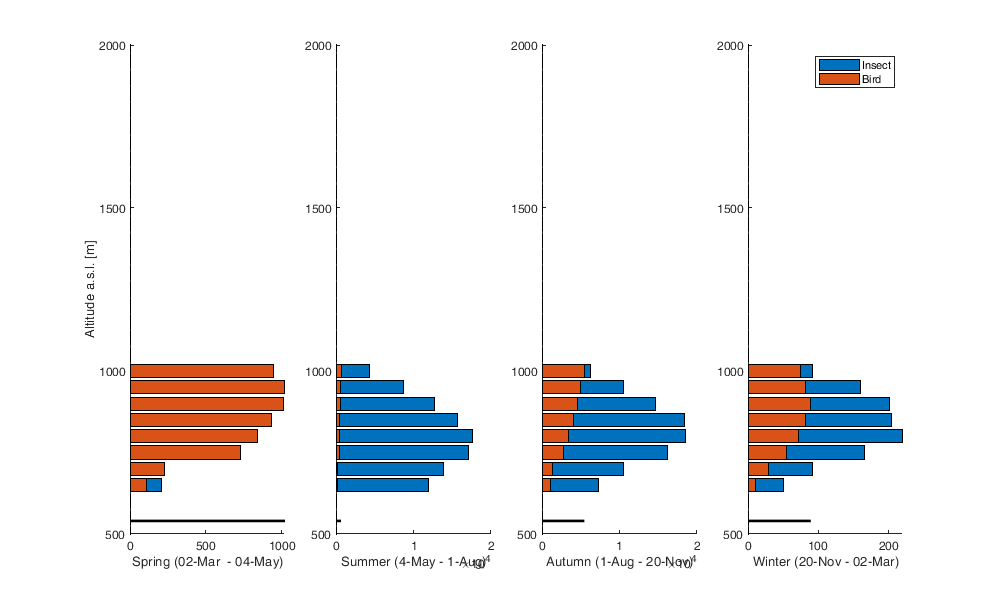

figure('position',[0 0 1000 600]); hold on;
edge=0:50:3000;
%edge=0:200:3000;
for i_s=1:numel(season)-1
    subplot(1,4,i_s); hold on;
    i_t = ~BSs.isBird & BSs.time_string>season(i_s) & BSs.time_string < season(i_s+1);
    counts = histcounts(BSs.altitude(i_t)+alt,edge);
    barh(edge(1:end-1)+diff(edge),counts)
    i_t = BSs.isBird & BSs.time_string>season(i_s) & BSs.time_string < season(i_s+1);
    counts = histcounts(BSs.altitude(i_t)+alt,edge);
    barh(edge(1:end-1)+diff(edge),counts)
    if (i_s==1); ylabel('Altitude a.s.l. [m]'),end
    xlabel(season_label{i_s}); ylim([500 2000])
    plot([0 max(counts)],[alt alt],'k','LineWidth',2)
end
legend({'Insect','Bird'})

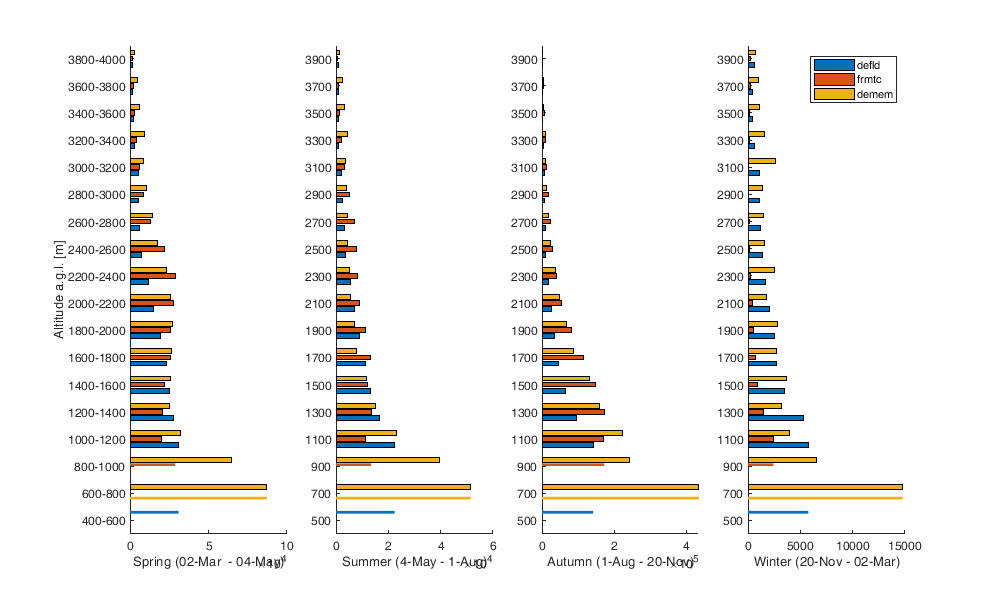

figure('position',[0 0 1000 600]); hold on;
%edge=0:200:3000;
for i_s=1:numel(season)-1
    subplot(1,4,i_s); hold on;
    i_t = dc(1).time>season(i_s) & dc(1).time < season(i_s+1);
    a=nan(25,numel(ii_d));
    for i_d=1:numel(ii_d)
        a(:,i_d) = nansum(dc(ii_d(i_d)).dens3(i_t,:));
        a(1:dc(ii_d(i_d)).scatter_lim-1,:)=nan;
    end
    barh(dc(1).alt,a,'grouped');
    yticks(dc(1).alt); 
    if (i_s==1)
        ylabel('Altitude a.s.l. [m]')
        yticklabels(num2str(bsxfun(@plus,dc(1).alt',[-100 100]),'%d-%d'))
    end
    set(gca, 'ColorOrder', circshift(get(gca, 'ColorOrder'), 3))
    for i_d=1:numel(ii_d)
        plot([0 max(a(:,i_d))],[dc(ii_d(i_d)).heightDEM dc(ii_d(i_d)).heightDEM],'LineWidth',2)
    end
    xlabel(season_label{i_s}); ylim([400 4000])
end
legend({dc(ii_d).name})

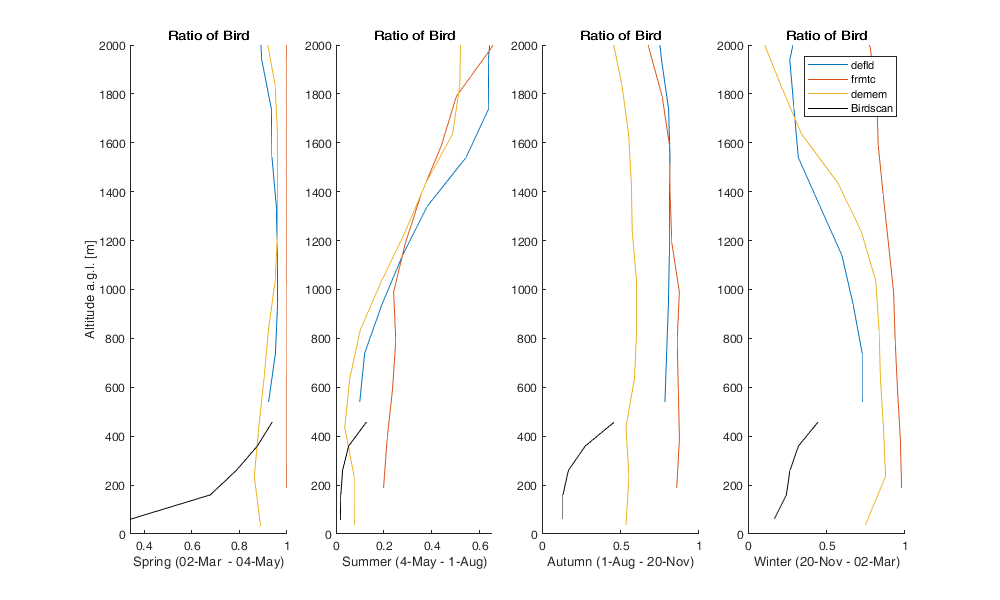

figure('position',[0 0 1000 600]); hold on;
edge=0:100:3000;
for i_s=1:numel(season)-1
    subplot(1,4,i_s); hold on;
    i_t = dc(1).time>season(i_s) & dc(1).time < season(i_s+1);
    a=nan(25,numel(ii_d)); b=a;
    for i_d=1:numel(ii_d)
        a(:,i_d) = nansum(dc(ii_d(i_d)).dens3(i_t,:) .* dc(ii_d(i_d)).bird(i_t,:));
        b(:,i_d) = nansum(dc(ii_d(i_d)).dens3(i_t,:) .* dc(ii_d(i_d)).insect(i_t,:));
        a(1:dc(ii_d(i_d)).scatter_lim-1,:)=nan;
        b(1:dc(ii_d(i_d)).scatter_lim-1,:)=nan;
    end
    plot(a./(a+b), bsxfun(@minus,[dc(1).alt]',[dc(ii_d).heightDEM]));
    
    i_t = ~BSs.isBird & BSs.time_string>season(i_s) & BSs.time_string < season(i_s+1);
    [countsi,~] = hist(BSs.altitude(i_t)+alt,edge);
    i_t = BSs.isBird & BSs.time_string>season(i_s) & BSs.time_string < season(i_s+1);
    [countsb,bins] = hist(BSs.altitude(i_t)+alt,edge);
    plot(countsb./(countsi+countsb),bins-alt,'k')
    
%     yticks(dc(1).alt); 
    if (i_s==1)
        ylabel('Altitude a.g.l. [m]')
       % yticklabels(num2str(bsxfun(@plus,dc(1).alt',[-100 100]),'%d-%d'))
    end
    xlabel(season_label{i_s}); ylim([0 2000])
    title('Ratio of Bird')
end
legend({dc(ii_d).name 'Birdscan'});

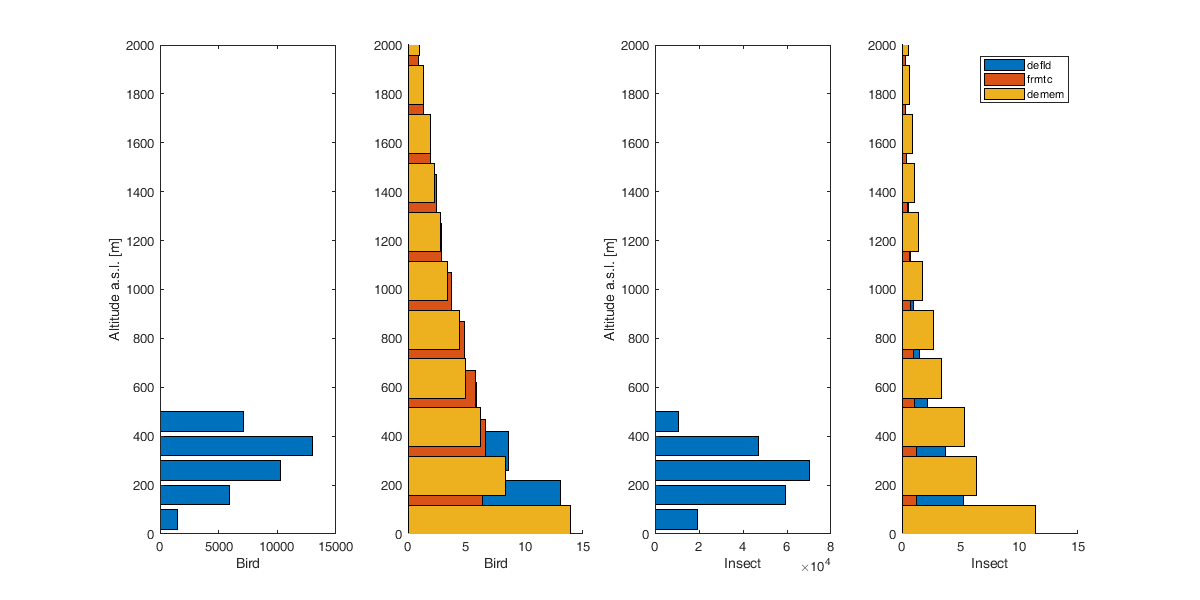

figure('position',[0 0 1200 600]); hold on;
subplot(1,4,1);
[counts,bins] = hist(BSs.altitude(BSs.isBird)+alt,edge);
barh(bins-alt,counts)
ylabel('Altitude a.s.l. [m]'); xlabel('Bird')
ylim([0 2000])

subplot(1,4,2); hold on;
a=nan(25,numel(ii_d));
for i_d=1:numel(ii_d)
    a(:,i_d) = nanmean(dc(ii_d(i_d)).dens3 .* dc(ii_d(i_d)).bird);
    a(1:dc(ii_d(i_d)).scatter_lim-1,:)=nan;
    barh(dc(1).alt-dc(ii_d(i_d)).heightDEM,a(:,i_d));
end
%yticks(dc(1).alt); 
% yticklabels(num2str(BSsxfun(@plus,dc(1).alt',[-100 100]),'%d-%d'))
ylim([0 2000]); xlim([0 15]);xlabel('Bird')

subplot(1,4,3);
[counts,bins] = hist(BSs.altitude(~BSs.isBird)+alt,edge);
barh(bins-alt,counts)
ylabel('Altitude a.s.l. [m]'); xlabel('Insect')
ylim([0 2000])

subplot(1,4,4); hold on;
a=nan(25,numel(ii_d));
for i_d=1:numel(ii_d)
    a(:,i_d) = nanmean(dc(ii_d(i_d)).dens3 .* dc(ii_d(i_d)).insect);
    a(1:dc(ii_d(i_d)).scatter_lim-1,:)=nan;
    barh(dc(1).alt-dc(ii_d(i_d)).heightDEM,a(:,i_d));
end
%yticks(dc(1).alt); 
% yticklabels(num2str(BSsxfun(@plus,dc(1).alt',[-100 100]),'%d-%d'))
ylim([0 2000]); xlim([0 15]); xlabel('Insect'); 
legend({dc(ii_d).name})

## Daily aggregate

Define altitudinal overlap

alt_thr = alt+[60 460];

Daily

daily_nb = nan(numel(t),2,1+numel(ii_d));
%daily_mtr = nan(numel(t),4);
tmp1 = dateshift(BSs.time_string(~BSs.isBird & BSs.altitude+alt>alt_thr(1)  & BSs.altitude+alt<alt_thr(2)),'start','day','nearest');
tmp2 = dateshift(BSs.time_string(BSs.isBird  & BSs.altitude+alt>alt_thr(1)  & BSs.altitude+alt<alt_thr(2)),'start','day','nearest');
id_alt = dc(1).alt-100>=alt_thr(1) & dc(1).alt+100<=alt_thr(2);
tmp3 = dateshift(dc(1).time,'start','day','nearest');
for i_t=1:numel(t)
    %BSs
    id_i = t(i_t)==tmp1;
    id_b = t(i_t)==tmp2;
    daily_nb(i_t,1,1) = sum(id_i); % insect
    daily_nb(i_t,2,1) = sum(id_b); % bird

    % Compute a sort of MTR just not normalized for the area cover, but as it is a cst, it doesn't matter.
    %daily_mtr(i_t,1) = aBSs(nanmean(BSs(~BSs.isBird).groundSpeed(id_i) .* exp( deg2rad(BSs(~BSs.isBird).direction(id_i))*1i)) * numel(id_i)) % bird * m/s
    %daily_mtr(i_t,2) = aBSs(nanmean(BSs(BSs.isBird).groundSpeed(id_b) .* exp( deg2rad(BSs(BSs.isBird).direction(id_b))*1i)) * numel(id_b)) % bird * m/s
    
    % WR
    id_t = t(i_t)==tmp3;
    for i_d= 1:numel(ii_d)
        daily_nb(i_t,1,i_d+1) = nansum(nansum(dc(ii_d(i_d)).dens3(id_t,id_alt).* dc(ii_d(i_d)).insect(id_t,id_alt) .*0.2 )); % insect
        daily_nb(i_t,2,i_d+1) = nansum(nansum(dc(ii_d(i_d)).dens3(id_t,id_alt).* dc(ii_d(i_d)).bird(id_t,id_alt) .*0.2 )); % bird
    end
end

Filter by 50 tracks minimum during the night

daily_nb(daily_nb<30)=nan;

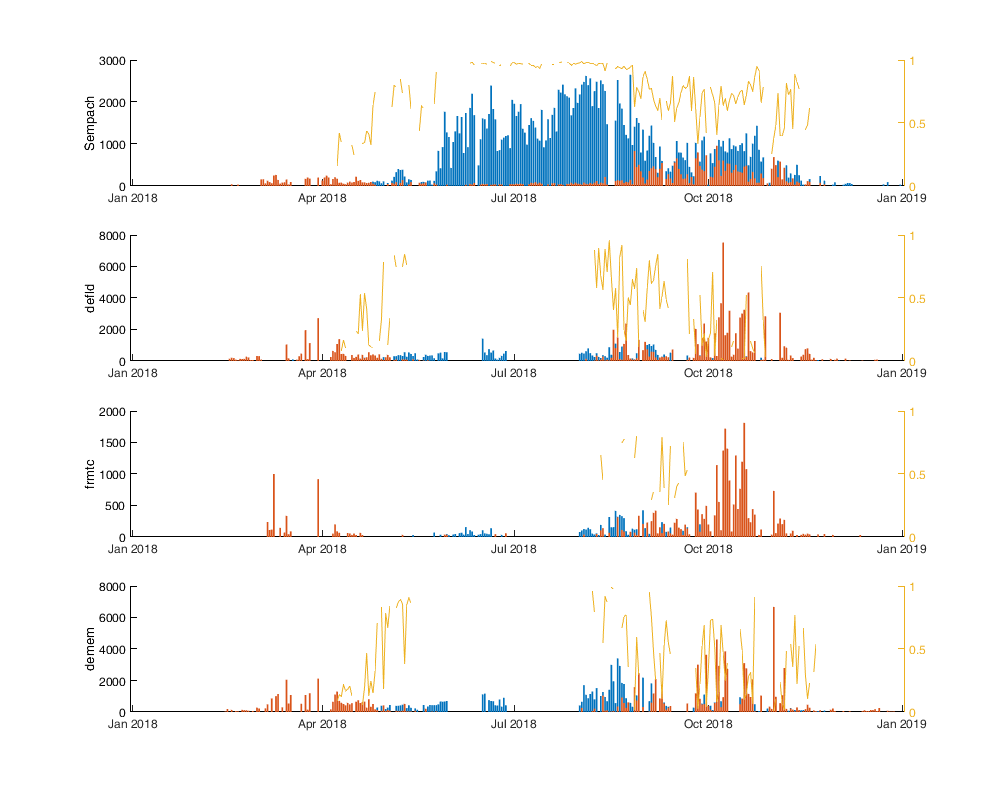

label = {'Sempach', dc(ii_d).name};
figure('position',[0 0 1000 800]); 
for i=1:size(daily_nb,3)
    subplot(size(daily_nb,3),1,i); hold on;
    bar(t,daily_nb(:,1,i),'EdgeColor','none')
    bar(t,daily_nb(:,2,i),'EdgeColor','none')
    ylabel(label{i})
    yyaxis right; plot(t, daily_nb(:,1,i)./sum(daily_nb(:,:,i),2))
end

## Ratio Insect vs Bird

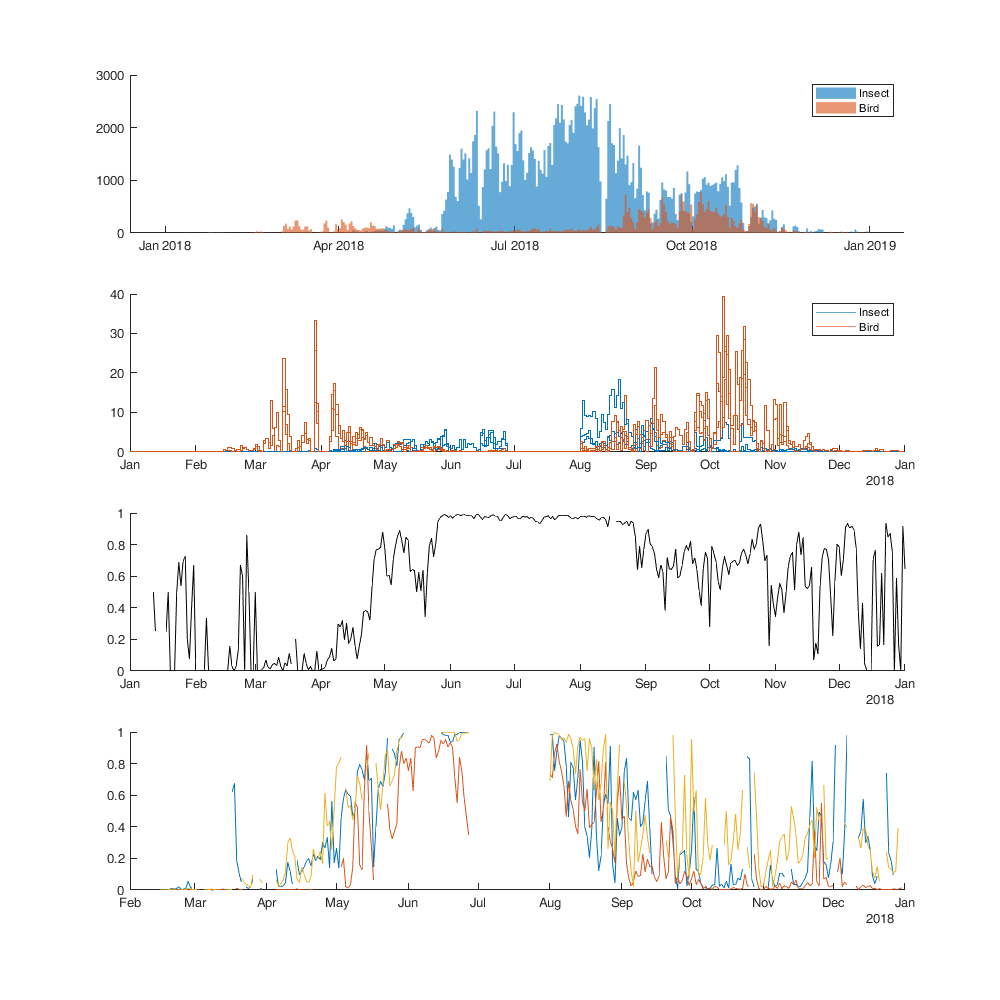

figure('position',[0 0 1000 1000]); 
subplot(4,1,1); hold on;
hi=histogram(BSs.time_string(~BSs.isBird),t,'EdgeColor','none');
hb=histogram(BSs.time_string(BSs.isBird),t,'EdgeColor','none');
legend({'Insect','Bird'})

subplot(4,1,3); hold on;
plot(t(1:end-1)+diff(t),hi.Values./(hi.Values+hb.Values),'k')

c = get(gca,'colororder');
[G,dy] = findgroups(dateshift(dc(1).time,'start','day'));
for i_d=1:numel(ii_d)
    bir = dc(ii_d(i_d)).dens3 .* dc(ii_d(i_d)).bird;
    ins = dc(ii_d(i_d)).dens3 .* dc(ii_d(i_d)).insect;
    
    vidh = min(max(dc(ii_d(i_d)).alt+100-dc(ii_d(i_d)).heightDEM,0),200)/1000;
    
    biri = nansum(bir .* repmat(vidh,numel(dc(1).time),1),2);
    insi = nansum(ins .* repmat(vidh,numel(dc(1).time),1),2);
    
    birid = splitapply(@nanmean,biri,G');
    insid = splitapply(@nanmean,insi,G');
    
    subplot(4,1,2); hold on;
    stairs(dy,insid','Color',c(1,:))
    stairs(dy,birid','Color',c(2,:))
    legend({'Insect','Bird'})
    
    subplot(4,1,4); hold on;
    plot(dy, insid./(insid+birid))
end